# Frequency Domain Filtering - Overlap-Save Method

Implement the Frequency Domain Filtering between $x[n]$ and $h[n]$ .

**Parameters** 

- 
$$x[n] = cos(2 \pi F_{0} nT_s) + cos(2 \pi F_1 n T_s)$$


- F_0 = 31.25 [Hz]

- F_1 = 312.5 [Hz]

- F_s = 1 [kHz];

- N=256; M = 129;

- h = fir1(M-1,0.25);

**Notes**

DFT  --> X = fft(x,N)  where N is the length of the transform

IDFT --> x = ifft(X,N) where N is the length of the transform

## Clear

clc;            % Clear the text from the Command Window
clear;          % Remove all variables from the current workspace
close all;      % Close all figures

## Parameters

Fc0 = 31.25;
Fc1 = 312.5;
Fs = 1000;
Ts = 1/Fs;

N = 256;    % FFT Points
M = 129;    % Length of the filter
h = fir1(M-1,0.25).';

## Exercise

len = 1e4;
n = 0:len-1;
x = cos(2*pi*Fc0*n*Ts).' + cos(2*pi*Fc1*n*Ts).';

% Overlap and Zero-Padding
xm = buffer(x,N,N/2);
hm = [h; zeros(N-M,1)];

% DFT
H  = fft(hm,N);
Xm = fft(xm,N);

% Product
Ym = zeros(size(Xm));
for i=1:size(Xm,2)
    Ym(:,i) = Xm(:,i) .* H;
end

% IDFT
ym = real(ifft(Ym,N));

% Reject
y = ym(N/2+1:N,:);  % Reject
y = y(:);           % Matrix to vector

% Linear Convolution
y_L = conv(x,h);


## Plot

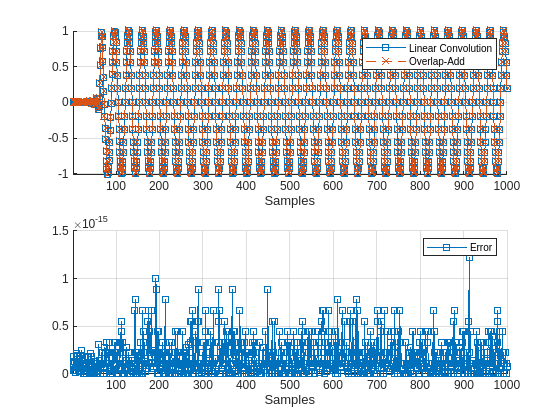

len_err = min([length(y_L),length(y)]);
error = y_L(1:len_err)-y(1:len_err);
error = abs(error);

hfvt = fvtool(x,1,y_L(1:len_err),1,y(1:len_err),1);
legend(hfvt, {'x','Linear Convolution', 'Overlap-Add'})

figure;
subplot(2,1,1)
    hold on
    plot(y_L,'s-')
    plot(y,'x--')
    hold off
    xlim([1,1e3])
    legend({'Linear Convolution', 'Overlap-Add'})
    grid on
    xlabel('Samples')
subplot(2,1,2)
    hold on
    plot(error,'s-')
    hold off
    xlim([1,1e3])
    legend({'Error'})
    grid on
    xlabel('Samples')